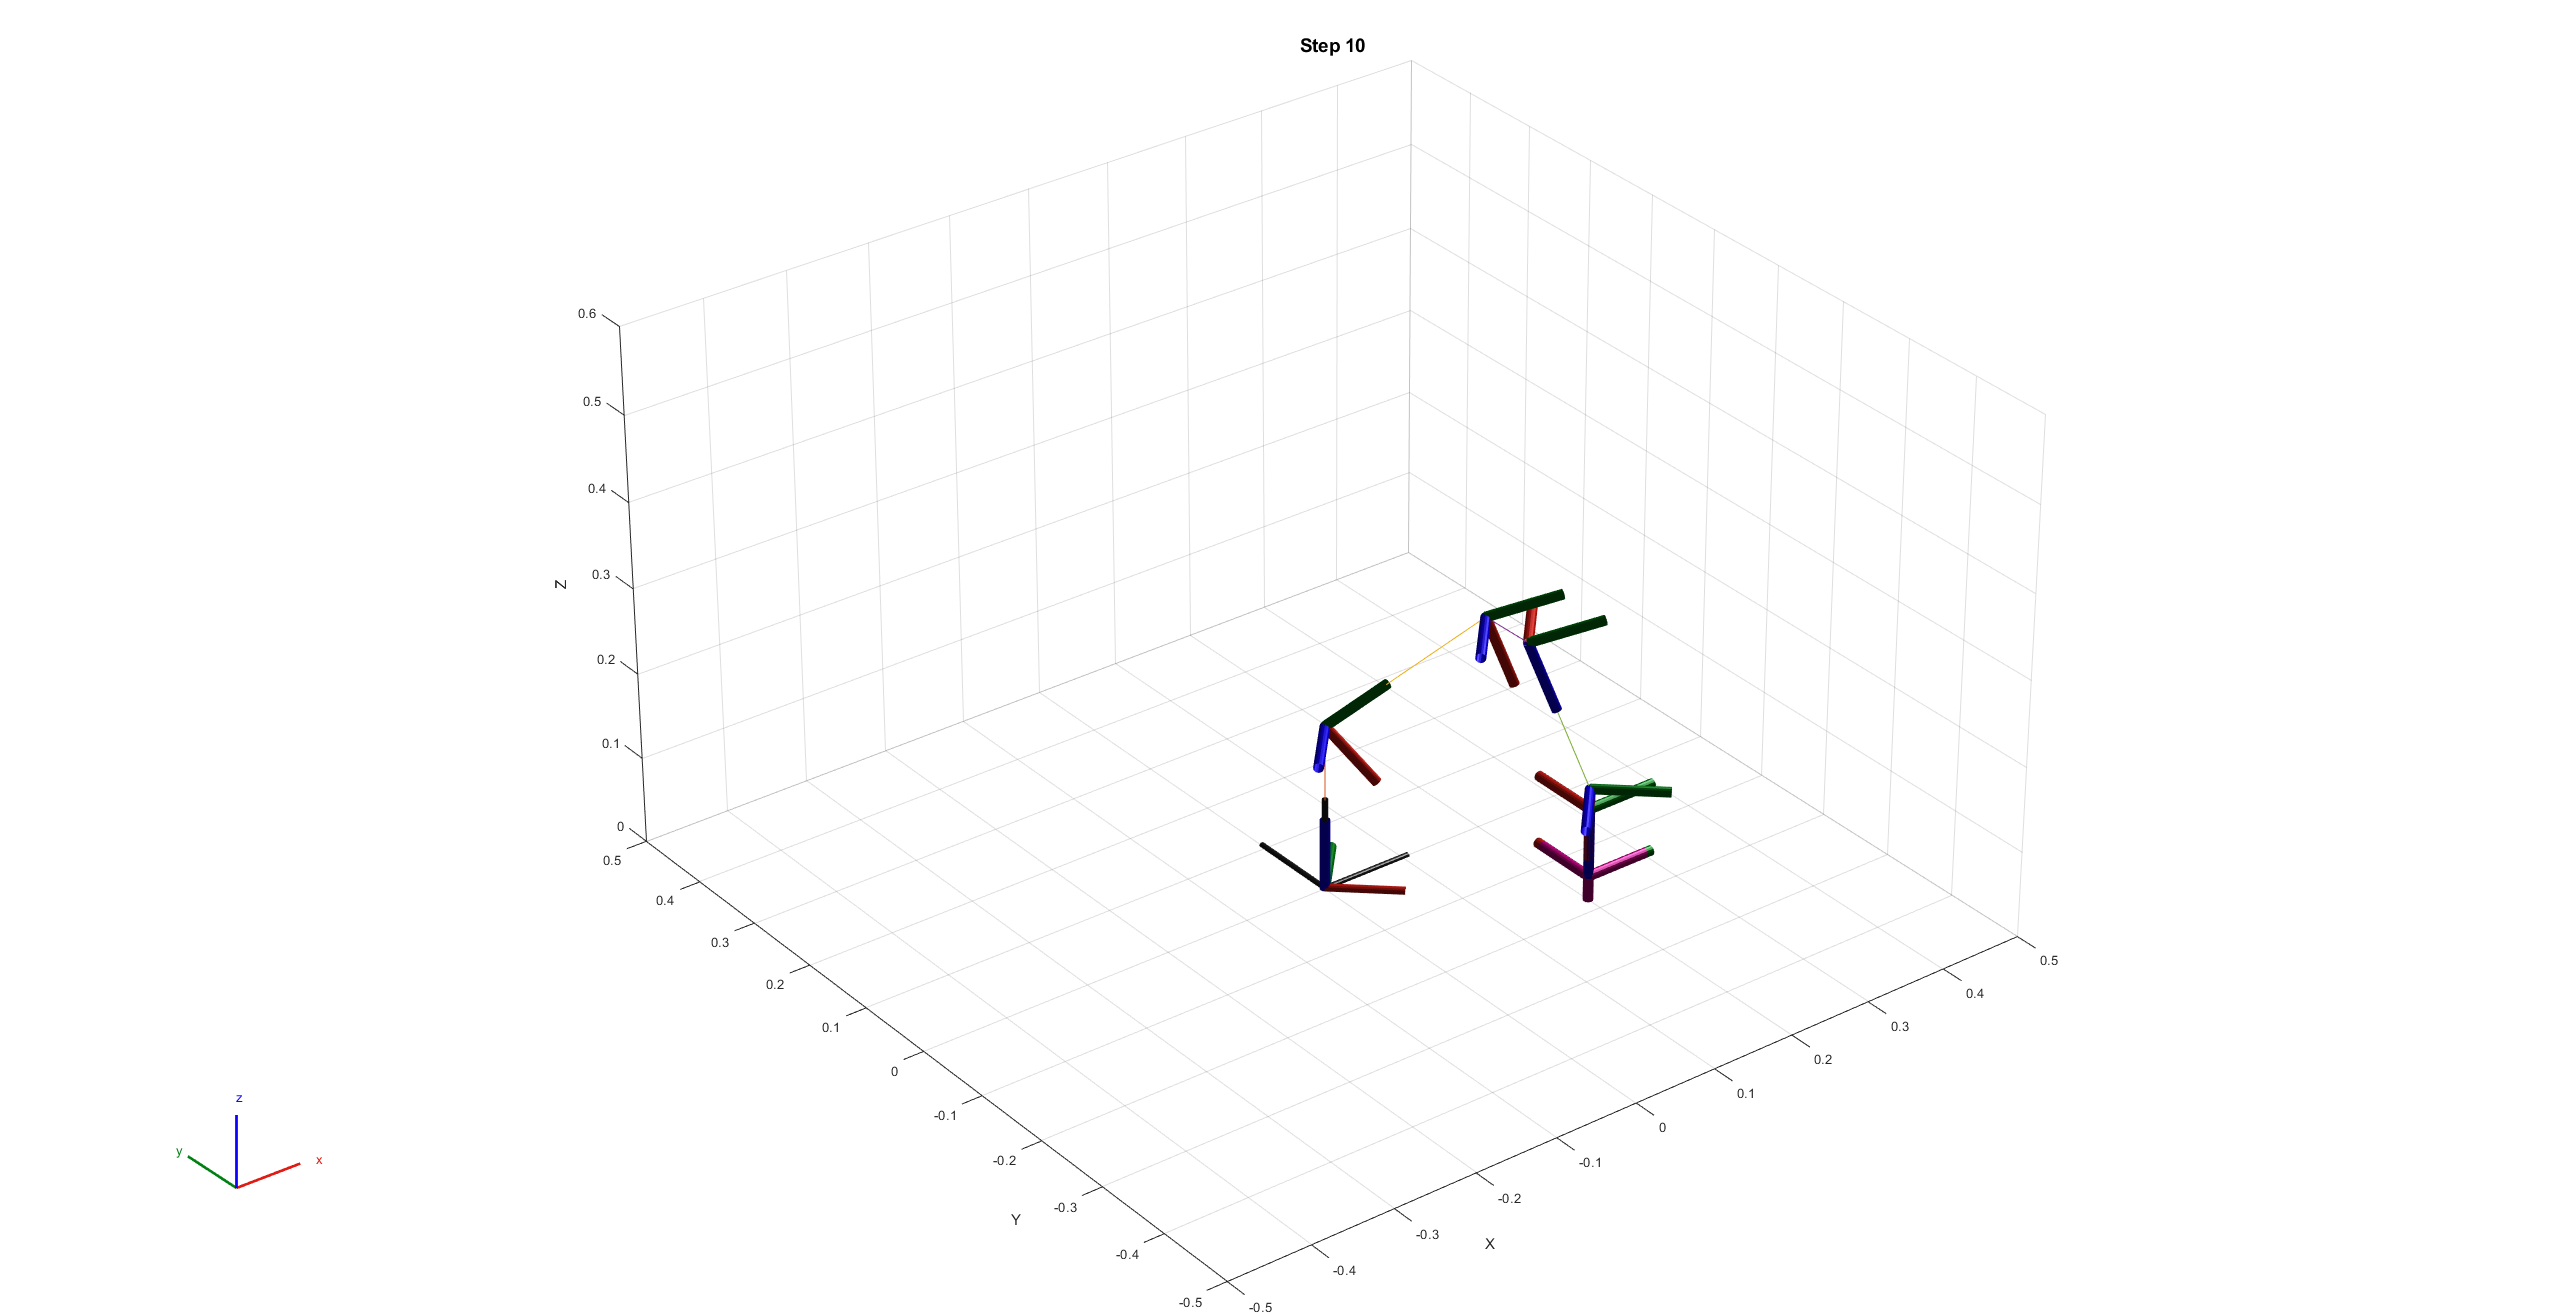

close all
clear

% --- Define the robot ---
robot = rigidBodyTree('DataFormat','struct');

% Body 1
body1 = rigidBody('body1');
jnt1 = rigidBodyJoint('jnt1', 'revolute');
jnt1.PositionLimits = [-3.05433, 3.05433];
setFixedTransform(jnt1, trvec2tform([0, 0, 0]));
body1.Joint = jnt1;
addBody(robot, body1, 'base');

% Body 2
body2 = rigidBody('body2');
jnt2 = rigidBodyJoint('jnt2', 'revolute');
setFixedTransform(jnt2, trvec2tform([0, 0, 0.193]) * eul2tform([0, 0, pi/2]));
jnt2.PositionLimits = [-1.5708, 0.6405358];
body2.Joint = jnt2;
addBody(robot, body2, 'body1');

% Body 3
body3 = rigidBody('body3');
jnt3 = rigidBodyJoint('jnt3', 'revolute');
setFixedTransform(jnt3, trvec2tform([0, 0.21, 0]));
jnt3.PositionLimits = [-1.39626, 1.5708];
body3.Joint = jnt3;
addBody(robot, body3, 'body2');

% Body 4
body4 = rigidBody('body4');
jnt4 = rigidBodyJoint('jnt4', 'revolute');
setFixedTransform(jnt4, trvec2tform([0.0415, 0.03, 0]) * eul2tform([0, pi/2, 0]));
jnt4.PositionLimits = [-3.05433, 3.05433];
body4.Joint = jnt4;
addBody(robot, body4, 'body3');

% Body 5
body5 = rigidBody('body5');
jnt5 = rigidBodyJoint('jnt5', 'revolute');
setFixedTransform(jnt5, trvec2tform([0, 0, 0.180]) * eul2tform([0, -pi/2, 0]));
jnt5.PositionLimits = [-1.74533, 1.91986];
body5.Joint = jnt5;
addBody(robot, body5, 'body4');

% Body 6
body6 = rigidBody('body6');
jnt6 = rigidBodyJoint('jnt6', 'revolute');
setFixedTransform(jnt6, trvec2tform([0.0237, 0, 0]) * eul2tform([0, pi/2, 0]));
jnt6.PositionLimits = [-2.5743606, 2.5743606];
body6.Joint = jnt6;
addBody(robot, body6, 'body5');

% End effector
body7 = rigidBody('body7');
jnt7 = rigidBodyJoint('jnt7', 'fixed');
setFixedTransform(jnt7, trvec2tform([0, 0, 0.08]));
body7.Joint = jnt7;
addBody(robot, body7, 'body6');

% --- Target positions ---
positions = [
    0.30, 0.00, 0.3;
    0.15, 0.15, 0.025;
    0.2,  0.18, 0.1;
    0.2,  0.18, 0.0001;
    0.25, 0.16, 0.1;
    0.25, 0.16, 0.0001;
    0.2, -0.18, 0.1;
    0.2, -0.18, 0.008;
    0.2, -0.18, 0.018;
    0.2, -0.18, 0.028
];

% --- IK setup ---
ik = inverseKinematics("RigidBodyTree", robot);
weights = [0.9 0.9 0.9 1 1 1];
initialguess = homeConfiguration(robot);
ros = [1.5*pi, pi, 0]; % Constant orientation

% Compute all configurations
configs = zeros(size(positions, 1), numel(initialguess));

for i = 1:size(positions, 1)
    pos = positions(i, :);
    poseTF = trvec2tform(pos) * eul2tform(ros);
    [configSoln, ~] = ik("body7", poseTF, weights, initialguess);
    configs(i, :) = [configSoln.JointPosition];
end

% --- Animate ---
fig = figure('Color', 'w');
filename = 'robot_motion_loop.gif';
loopFrames = 2; % Number of times to loop through all poses

for loop = 1:loopFrames
    for i = 1:size(configs, 1)
        % Rebuild configuration struct
        configStruct = initialguess;
        for j = 1:numel(configStruct)
            configStruct(j).JointPosition = configs(i, j);
        end

        show(robot, configStruct, 'PreservePlot', false, 'Frames', 'on', 'Visuals', 'on');
        title(['Step ' num2str(i)], 'FontSize', 14)
        view(3)
        axis equal
        xlim([-0.5 0.5]); ylim([-0.5 0.5]); zlim([0 0.6]);
        drawnow

        % Capture frame and write to GIF
        frame = getframe(fig);
        im = frame2im(frame);
        [A,map] = rgb2ind(im,256);

        if i == 1 && loop == 1
            imwrite(A, map, filename, 'gif', 'LoopCount', inf, 'DelayTime', 0.4);
        else
            imwrite(A, map, filename, 'gif', 'WriteMode', 'append', 'DelayTime', 0.4);
        end
    end
end